%optional params
dt=0.1; %step time
n=90;  %total simulation steps

global pc m1 m2 G F0;
pc=[5,5];   %circle center (solar)
r=1;
m1=5;   %mass of the solar
m2=5;   %mass of the planet
G=1;    %gravitational constant  at will 
p0=pc+[r,0];    %init position
F0=[-G.*m1.*m2./(r.^2),0];  %init force [-5,0];
v0=[0, -sqrt(norm(F0).*r./m2)];    %init velocity [0,-1];

%trajectory ground truth (a circle)

theta=linspace(0,2*pi,10*n);
pt_truth=pc+[r.*[cos(theta)]',r.*[sin(theta)]'];

%trajectory simulation use explicity Euler's method

pt1=zeros(n,2);
vt1=zeros(n,2);
Ft1=zeros(n,2);
pt1(1,:)=p0;
vt1(1,:)=v0;
Ft1(1,:)=F0;

for i=2:n
    vt1(i,:)=vt1(i-1,:)+Ft1(i-1,:)./m2.*dt; %use current F
    pt1(i,:)=pt1(i-1,:)+vt1(i-1,:).*dt;     %use current v
    Ft1(i,:)=ForceAtPosition(pt1(i,:));
end

%trajectory simulation use semi-implicity Euler's method

pt2=zeros(n,2);
vt2=zeros(n,2);
Ft2=zeros(n,2);
pt2(1,:)=p0;
vt2(1,:)=v0;
Ft2(1,:)=F0;

for i=2:n
    vt2(i,:)=vt2(i-1,:)+Ft2(i-1,:)./m2.*dt; %use current F
    pt2(i,:)=pt2(i-1,:)+vt2(i,:).*dt;       %use next v
    Ft2(i,:)=ForceAtPosition(pt2(i,:));
end

%plot the trajectory

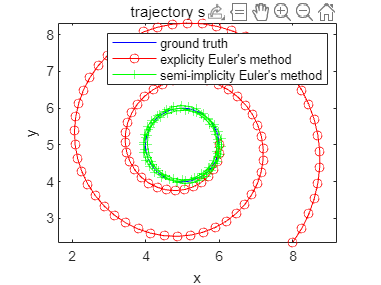

% 创建 pt_truth_x 和 pt_truth_y 的 plot
h = plot(pt_truth(:,1),pt_truth(:,2),"-b");
axis equal;
hold on;
plot(pt1(:,1),pt1(:,2),"-ro");
plot(pt2(:,1),pt2(:,2),"-g+");
hold off;

% 添加 xlabel, ylabel, title 和 legend
xlabel("x")
ylabel("y")
title("trajectory simuation")
legend("ground truth","explicity Euler's method","semi-implicity Euler's method")

%Function to caculate the Force vecter of the planet at 2D space point p  

function Fp=ForceAtPosition(p)
global pc m1 m2 G F0;
pv=p-pc;    %vecter of p and center
dis=sqrt(sum(pv.^2,2)); %distance between point p and the solar
Fv=-pv./dis;    %normalize pv->orientation of force
%F=G.*m1.*m2./(dis.^2);      %
F=norm(F0);     %use const force just for better graph effect
Fp=Fv.*F;
end